clear; close all; clc

## 64-Electrode EEG Sliding Window Power Spectra with BM3

First we call the homeDir() function to add function library to path and change to home directory

homeDir

We can access a desired dataset by specficying its dataset ID. From the ID we can use the decodeID() function to get referential input strings.

[YEAR, MONTH, DAY, TRIAL, USER, DEVICE] = ...
    decodeID('2019_12_2_T03_U001_EEG01_');

Now we can easily compute the power spectra of 64 electrode EEG for the data corresponding to the string inputs. NOTE: last input of EEGPowerSpectra function is the number of workers desired for parallel processing. If you do not wish to use parallel processing leave it as [] (but it may take a while).

EEGPowerSpectra(YEAR, MONTH, DAY, TRIAL, USER, ...
    DEVICE, 6)

A data structure with the power spectra data is now saved to directory: *objects/2019/12/5/T05/U011/EEG01*

We can access the data structure using the LoadObject() function.

% define object name
ObjectName = 'EEGps';

% load EEG power spectra data structure
EEGps = LoadObject(YEAR, MONTH, DAY,...
    TRIAL, USER, DEVICE, ObjectName);

Once the data structure is loaded we can see the different fields of the strucuture including: sampleRate, epochTimeInSeconds, powerSpectrumWindowLength, frequencyValues, and a Timetable with the power spectra at each timestep

EEGps

EEGps = struct with fields:
                       sampleRate: 500
               epochTimeInSeconds: 10
                   psWindowLength: 5001
                  frequencyValues: [257×1 double]
    Timetable_groupedByElectrodes: [24236×16448 timetable]


From this, we can get the alpha band (8-12 Hz) power values with the getAlphaBand() function. This yields an array with coulmns corresponding to the alpha power for each electrode and rows to timesteps.

alphaBand = getAlphaBand(EEGps);

Finally we can use the EEGLAB library to plot the power values at each time step. 

We can import the EEGLAB functions via the addEEGLabFunctions() function and load EEG channel locations for visualization

addEEGLabFunctions
load('EEG01_chanlocs.mat') % located in ./backend/channelLocations

Then plot the which ever timestep we want

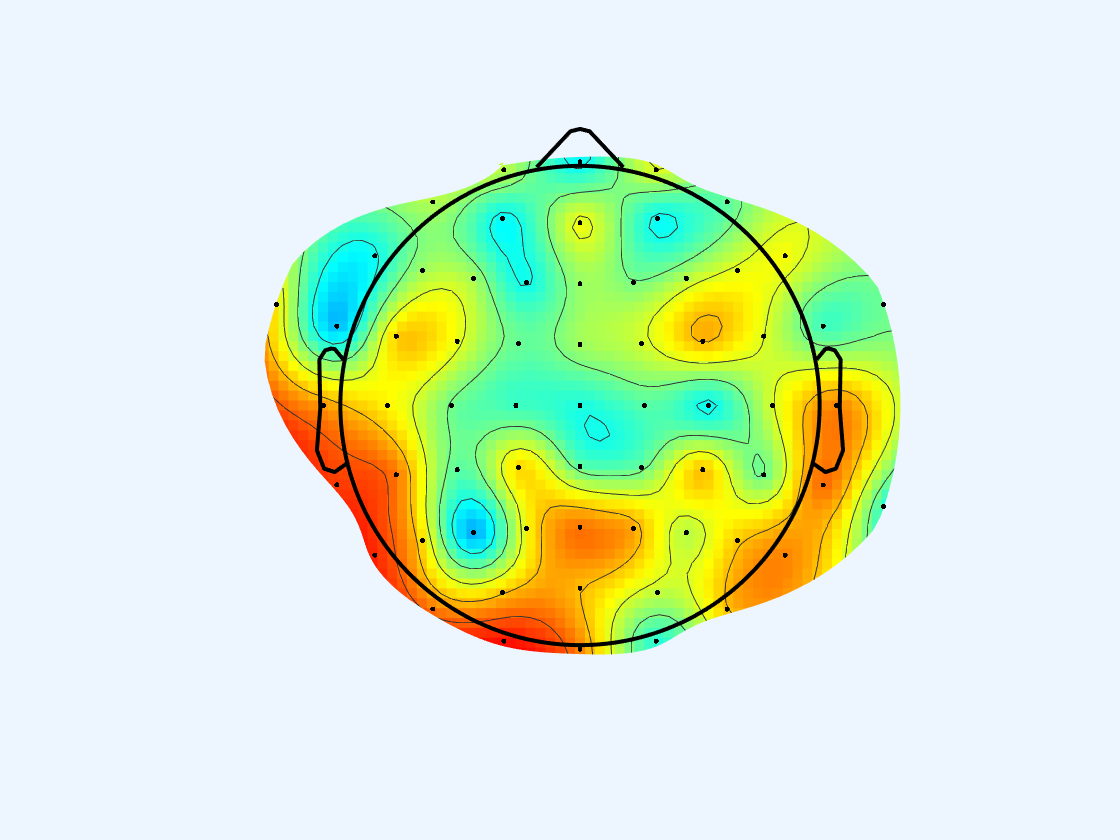

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [67×67 double]
           YData: [67×67 double]
           ZData: [67×67 double]
           CData: [67×67 double]

  Show all properties


topoplot(alphaBand(10000,:), EEG01_chanlocs, 'conv', 'on');